# Simulated Place Decoding

## Place field profiles:

Simulate place fields on a linear track, track length 16, place field width 1

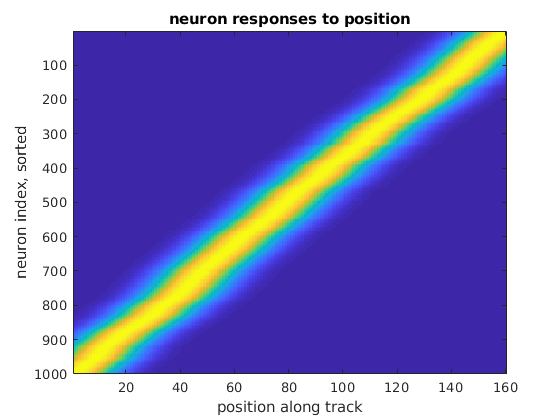

L = 16; N = 1000;
points = linspace(0,L,160);
means = sort(L*rand(N,1), 'descend');
stds = ones(N,1);
base_lambda = 0.05;
Lambdas = @(point) base_lambda .* ...
    (exp(-(point - means).^2./(2*stds.^2)));


responses = Lambdas(points);
figure;
imagesc(responses);
xlabel('position along track');
ylabel('neuron index, sorted');
title('neuron responses to position');

## Trajectory:

Trajectory is back and forth motion along track, ~160 times

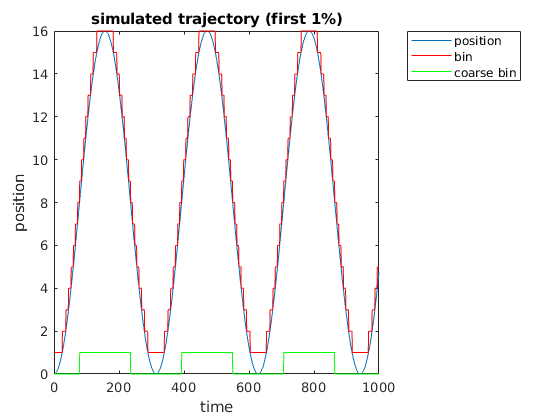

times = 1:100000; speed = 0.01;
trajectory = L*sin(speed*times).^2;
ks = ceil(trajectory);
ks_coarse = trajectory > 8;
figure;
plot(times(1:1000), trajectory(1:1000));
hold on;
plot(times(1:1000), ks(1:1000), 'r');
plot(times(1:1000), ks_coarse(1:1000), 'g');
legend position bin 'coarse bin' Location bestoutside
xlabel('time');
ylabel('position');
title('simulated trajectory (first 1%)');

## Simulated neural responses:

Based on the position from each trajectory, and based on the firing rate of each neuron as a function of position, construct the response patterns

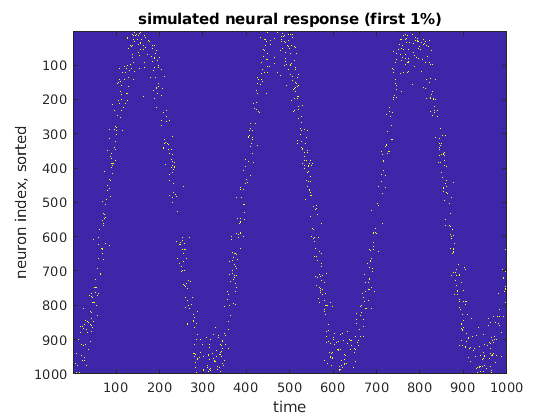

rates = Lambdas(trajectory);
X = double(sparse(rand(size(rates)) < rates))';
figure;
imagesc(X(1:1000,:)');
xlabel('time');
ylabel('neuron index, sorted');
title('simulated neural response (first 1%)');

## Decoding error:

Use misclassification rate as the error of the decoder, rather than mean distance

errf = @(k,p) mean(k(:)~=p(:));

Now run naive Bayes and linear SVM ensembles

algs = my_algs({'mvnb2', 'ecoclin_onevsall'}, {'original', 'shuf'});
par_loops = 4;
train_frac = 0.7;
for i = 1:numel(algs)
    [train_err{1,i}, test_err{1,i}] = evaluate_alg(algs(i),...
        X, ks, 'eval_f', errf,...
        'train_frac', train_frac, 'par_loops', par_loops);
    [train_err{2,i}, test_err{2,i}] = evaluate_alg(algs(i),...
        X, ks_coarse, 'eval_f', errf,...
        'train_frac', train_frac, 'par_loops', par_loops);
end

877.752115 s:running alg Bernoulli NB, with subset? 0


0.199791 s:running alg Bernoulli NB, with subset? 0


0.899520 s:running alg Bernoulli NB (shuf), with subset? 0


0.443201 s:running alg Bernoulli NB (shuf), with subset? 0


31.636748 s:running alg ECOC SVM (1 vs. all), with subset? 0


1.635087 s:running alg ECOC SVM (1 vs. all), with subset? 0


34.828648 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


1.470229 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


Displaying the results:

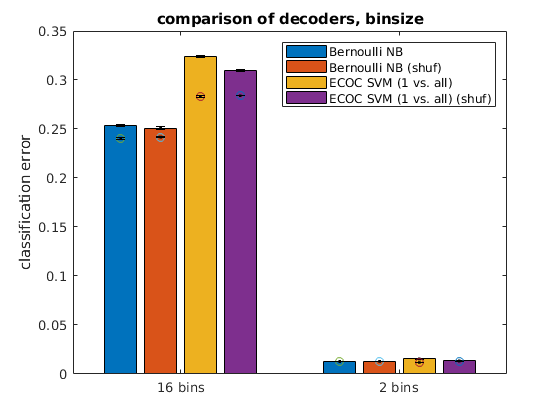

berr({'16 bins', '2 bins'}, test_err, train_err, {algs.name});
ylabel('classification error');
title('comparison of decoders, binsize');

Using a function for all of the above:

res_16 = field_bin_sim(16, 16);

0.870091 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.164154 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


res_2 =  field_bin_sim(2,  16);

0.054581 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.088493 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


for n_bins = 1:16
    fprintf('b%d|f=', n_bins);
    for n_fields = 1:16
        res{n_bins, n_fields} = field_bin_sim(n_bins, n_fields);
        fprintf(' %d', n_fields);
    end
    fprintf('\n');
end

0.145135 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.139421 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f1


0.051201 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.115769 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f2


0.044853 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.093446 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f3


0.039038 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.085342 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f4


0.041507 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.077581 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f5


0.035384 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.071756 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f6


0.037603 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.069015 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f7


0.033903 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.062564 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f8


0.036688 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.063518 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f9


0.032419 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.062423 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f10


0.034816 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.061023 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f11


0.031461 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.058959 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f12


0.033996 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.058199 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f13


0.030812 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.056387 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f14


0.033238 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.057335 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f15


0.030964 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.054453 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b1 f16


0.261447 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.258119 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f1


0.095534 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.227933 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f2


0.192086 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.117249 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f3


0.068933 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.107652 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f4


0.067460 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.110379 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f5


0.056117 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.087278 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f6


0.048888 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.081374 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f7


0.096290 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.079632 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f8


0.049865 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.075833 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f9


0.065361 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.080582 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f10


0.057885 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.074308 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f11


0.093243 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.073977 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f12


0.056117 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.079480 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f13


0.096614 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.074152 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f14


0.064495 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.105553 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f15


0.053964 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.078369 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b2 f16


0.569106 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.710713 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f1


0.720523 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.697875 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f2


0.310103 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.375734 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f3


0.283671 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.309118 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f4


0.257063 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.258872 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f5


0.191030 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.202557 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f6


0.229464 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.260139 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f7


0.210838 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.217914 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f8


0.183834 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.347445 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f9


0.500467 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.322091 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f10


0.192313 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.282967 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f11


0.249561 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.347276 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f12


0.203375 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.313043 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f13


0.257767 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.365632 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f14


0.221612 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.332604 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f15


0.231854 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.284801 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b3 f16


0.866422 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.058279 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f1


0.512433 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.577801 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f2


0.903994 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.212741 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f3


0.389955 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.519515 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f4


0.303966 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.415538 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f5


0.312193 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.335074 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f6


0.293153 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.350114 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f7


0.294183 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.360244 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f8


0.230008 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.351570 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f9


0.372447 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.338503 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f10


0.254931 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.402062 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f11


0.259756 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.405377 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f12


0.308913 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.349641 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f13


0.540268 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.555555 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f14


0.346316 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.415698 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f15


0.310495 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.406881 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b4 f16


1.341749 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.397594 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f1


0.571461 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.882179 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f2


0.674232 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.219909 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f3


0.808526 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.003459 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f4


0.425130 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.470184 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f5


0.430021 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.447135 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f6


0.323974 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.421684 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f7


0.320171 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.371699 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f8


0.355067 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.470422 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f9


0.353658 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.380270 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f10


0.413573 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.423993 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f11


0.367764 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.413897 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f12


0.356326 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.461945 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f13


0.322861 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.513772 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f14


0.344060 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.382980 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f15


0.370136 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.444788 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b5 f16


1.490483 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.800975 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f1


0.624946 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.988913 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f2


0.723596 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.705613 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f3


1.376121 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.425731 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f4


0.582715 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.561398 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f5


0.468387 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.570681 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f6


0.436976 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.467494 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f7


0.368092 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.556309 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f8


0.430773 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.454438 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f9


0.504958 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.451660 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f10


0.368714 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.553860 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f11


0.495432 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.504539 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f12


0.427253 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.463002 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f13


0.430187 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.505119 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f14


0.485368 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.458535 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f15


0.395136 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.442586 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b6 f16


2.000015 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.120876 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f1


1.105330 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.012436 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f2


0.786070 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.834897 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f3


1.002852 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.845175 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f4


1.490274 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.339754 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f5


0.644749 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.958113 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f6


0.556312 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.629008 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f7


0.783399 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.139684 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f8


0.440973 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.533165 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f9


0.449215 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.803925 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f10


0.453529 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.637978 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f11


0.945174 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.517281 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f12


0.511596 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.587127 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f13


0.439705 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.517314 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f14


0.461402 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.624492 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f15


0.449208 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.589682 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b7 f16


1.610758 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.658676 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f1


1.188054 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.198710 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f2


0.935260 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.936901 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f3


0.881110 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.948158 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f4


1.007751 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.106704 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f5


1.672320 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.707137 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f6


0.662482 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.046382 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f7


0.589252 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.692823 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f8


0.643147 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.608220 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f9


0.527275 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.626991 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f10


0.536936 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.711399 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f11


0.564465 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.634842 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f12


0.612673 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.780550 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f13


0.620106 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.616613 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f14


0.446384 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.670348 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f15


0.498890 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.550261 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b8 f16


1.360475 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.702401 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f1


1.077463 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.269422 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f2


0.863320 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.918887 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f3


0.893792 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.981012 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f4


0.848341 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.172091 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f5


1.558150 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.592010 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f6


1.137376 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.938283 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f7


0.664079 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.787556 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f8


0.569432 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.834309 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f9


0.591375 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.704332 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f10


0.621182 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.738522 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f11


0.557898 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.693206 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f12


0.612372 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.714316 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f13


0.485357 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.670863 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f14


0.514964 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.640897 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f15


0.521634 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.593195 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b9 f16


1.592827 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.879683 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f1


1.186759 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.644870 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f2


0.962723 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.023251 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f3


0.985508 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.988078 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f4


0.787978 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.136349 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f5


1.059303 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.374261 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f6


0.991394 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.331352 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f7


0.816508 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.989502 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f8


0.741586 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.924995 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f9


0.660504 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.799337 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f10


0.707056 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.031293 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f11


0.568968 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.704252 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f12


0.572008 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.852505 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f13


0.598242 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.695526 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f14


0.558296 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.839996 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f15


0.593599 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.805719 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b10 f16


1.617339 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.914710 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f1


1.348104 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.439941 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f2


1.086243 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.286248 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f3


1.107257 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.314515 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f4


1.025307 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.971684 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f5


0.833837 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.238152 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f6


1.246382 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.772327 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f7


1.153590 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.108799 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f8


0.868348 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.965400 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f9


0.709229 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.971938 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f10


0.703962 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.734643 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f11


0.595614 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.822119 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f12


0.784069 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.868288 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f13


0.706139 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.762525 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f14


0.794115 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.795841 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f15


0.568059 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.758818 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b11 f16


1.738517 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.018034 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f1


1.482490 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.701736 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f2


1.146827 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.312955 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f3


1.145183 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.106318 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f4


1.063192 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.076494 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f5


1.025448 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.094499 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f6


1.184069 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.343564 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f7


1.153514 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.526475 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f8


0.902880 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.056754 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f9


0.811667 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.003704 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f10


0.832769 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.158742 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f11


0.813959 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.841601 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f12


0.669582 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.750896 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f13


0.686151 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.755338 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f14


0.689420 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.984628 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f15


0.902846 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.904420 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b12 f16


2.022259 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.109391 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f1


1.510681 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.852390 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f2


1.309321 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.385651 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f3


1.040442 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.132813 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f4


0.928687 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.089415 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f5


0.991434 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.989401 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f6


1.062702 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.120619 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f7


1.184220 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.669413 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f8


0.889688 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.192970 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f9


0.890605 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.160364 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f10


0.873282 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.086198 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f11


0.810130 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.916226 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f12


1.017571 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.057952 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f13


0.830018 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.119134 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f14


0.792148 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.084865 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f15


1.002627 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.025914 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b13 f16


2.456416 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.480670 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f1


1.735841 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.842433 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f2


1.473398 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.698377 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f3


1.226834 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.356783 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f4


0.887143 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.205575 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f5


0.895443 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.194558 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f6


1.162578 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.310650 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f7


0.989370 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.438953 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f8


1.190164 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.297018 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f9


0.985433 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.222199 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f10


1.202477 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.298197 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f11


1.005751 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.246019 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f12


0.914827 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.266508 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f13


0.944042 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.038222 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f14


1.003252 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.066799 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f15


0.872265 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.167339 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b14 f16


1.895006 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.110863 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f1


1.787787 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.276327 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f2


1.406311 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.947245 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f3


1.251127 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.434827 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f4


1.008197 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.196790 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f5


0.998116 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.171557 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f6


0.986617 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.342756 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f7


0.969719 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.044581 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f8


1.250883 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.419152 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f9


1.222895 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.384415 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f10


0.906437 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.288458 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f11


1.014609 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.115125 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f12


0.877906 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.002587 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f13


0.964088 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.106584 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f14


0.931271 s:running alg ECOC SVM (1 vs. all), with subset? 0
0.991734 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f15


0.879704 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.086908 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b15 f16


2.194044 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.314783 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f1


1.991880 s:running alg ECOC SVM (1 vs. all), with subset? 0
2.114987 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f2


1.733906 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.920757 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f3


1.210831 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.355662 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f4


1.121841 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.268836 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f5


1.016830 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.202542 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f6


1.030931 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.164453 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f7


1.153458 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.258324 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f8


1.317056 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.386252 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f9


1.274651 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.360116 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f10


1.019817 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.317979 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f11


0.859408 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.181351 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f12


0.941829 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.059976 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f13


0.900087 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.060382 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f14


0.854091 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.075400 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f15


0.870373 s:running alg ECOC SVM (1 vs. all), with subset? 0
1.034391 s:running alg ECOC SVM (1 vs. all) (shuf), with subset? 0


b16 f16


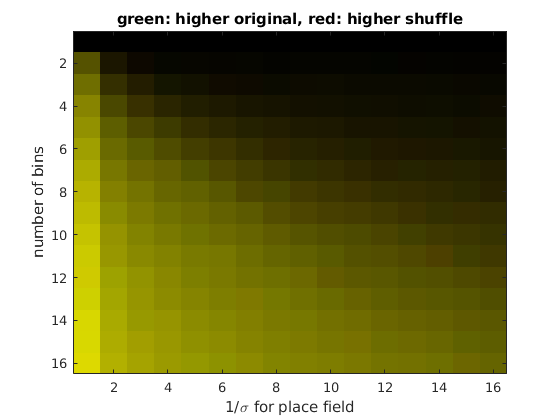

pixgen = @(r) cellfun(@mean, r.test);
datacell = cellfun(pixgen, res, 'UniformOutput',false);
img(:,:,1) = cellfun(@(x)x(1), datacell);
img(:,:,2) = cellfun(@(x)x(2), datacell);
img(:,:,3) = 0;
figure;
imagesc(img);
title('green: higher original, red: higher shuffle (test errors)');
xlabel('1/\sigma for place field');
ylabel('number of bins');

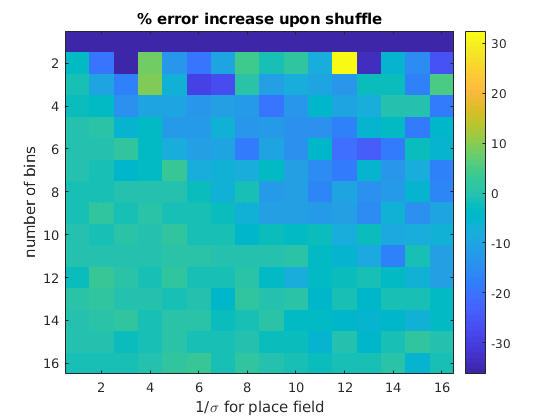

figure;
imagesc(100*(img(:,:,2)./img(:,:,1)-1));
colorbar;
title('% test error increase upon shuffle');
xlabel('1/\sigma for place field');
ylabel('number of bins');